% 灰色预测
clear
syms a b;
c=[a b]';
%125786
A=[1629 1490 1348 1346 1333 1271 1268 1237 1135 1025 957 884 826 774 761 768]

A =         1629        1490        1348        1346        1333        1271        1268        1237        1135        1025         957         884         826         774         761         768


%A=[126743 127627 128453 129227 129988 130756 131448 132129 132802 133450 134091 134735 135404 136072 136782 137462]/10000;
%A=[957 884 826    774    761    768    692    681    673    648    641    644    669    668    710    680]%1999-2015年增长值
B=cumsum(A) % 原始数据累加224.2955

B =         1629        3119        4467        5813        7146        8417        9685       10922       12057       13082       14039       14923       15749       16523       17284       18052


n=length(A);
for i=1:(n-1)
    C(i)=(B(i)+B(i+1))/2;  % 生成累加矩阵
end
% 计算待定参数的值
D=A;D(1)=[];
D=D';
E=[-C;ones(1,n-1)];
c=inv(E*E')*E*D;
c=c';
a=c(1)

a =         0.0495789241859484


b=c(2)

b =           1633.84410938453


value1=-b/a

value1 =          -32954.4082734977


value2=A(1)-b/a%[A(1)-b/a]*e^(-a*(i-1))-b/a

value2 =          -31325.4082734977


% 预测后续数据
F=[];F(1)=A(1);
for i=2:(n+16)
    F(i)=(A(1)-b/a)/exp(a*(i-1))+b/a ;
end
G=[];G(1)=A(1);
for i=2:(n+16)
    G(i)=F(i)-F(i-1); %得到预测出来的数据
end 
%模型检验

H = G(1:16);
%计算残差序列
epsilon = A - H;

%法一：相对残差Q检验
%计算相对误差序列
delta = abs(epsilon./A);
%计算相对误差Q
disp('相对残差Q检验：')

相对残差Q检验：


Q = mean(delta)

Q =         0.0392964514003523



%法二：方差比C检验
disp('方差比C检验：')

方差比C检验：


C = std(epsilon, 1)/std(A, 1)

C =          0.197896320919059



%法三：小误差概率P检验
S1 = std(A, 1);
tmp = find(abs(epsilon - mean(epsilon))< 0.6745 * S1);
disp('小误差概率P检验：')

小误差概率P检验：


P = length(tmp)/n

P =      1



t1=2000:2015;
t2=2000:2031;
G

G =                       1629           1515.2084774779          1441.91791697902          1372.17241733354          1305.80050412007          1242.63899712667          1182.53260916032          1125.33356426201          1070.90123438867          1019.10179366884          969.807889382002           922.89832885252          878.257781488581          835.776495233549          795.350026732383          756.878984550091          720.268784810556          685.429418655171          652.275230949403          620.724709693481          590.700285619074          562.128141479589           534.93803056507          509.063103995537          484.439746368054          461.007419353657          438.708512859404          417.488203389774          397.294319259032          378.077212323366          359.789635917277          342.386628694167


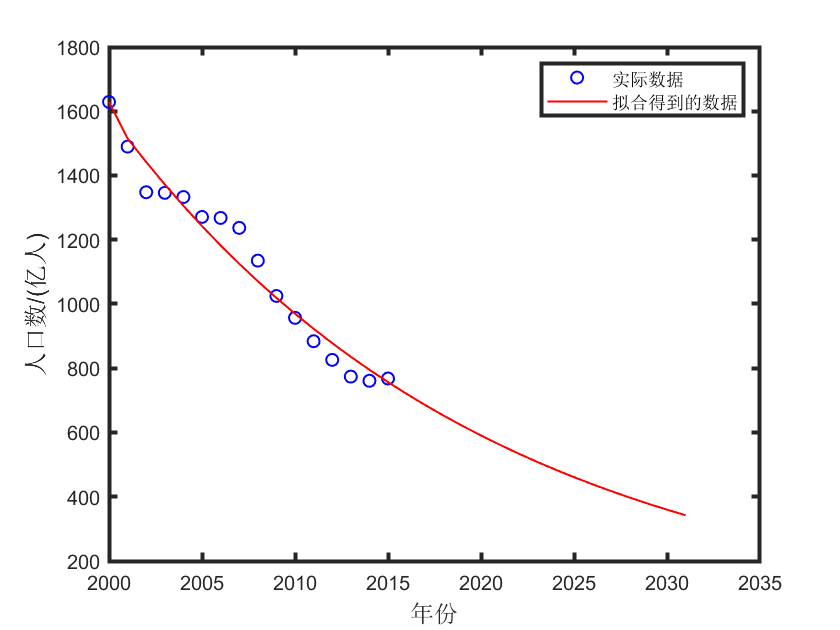

plot(t1,A,'bo', 'LineWidth',1)
hold on
plot(t2,G,'-r', 'LineWidth',1)
xlabel('年份', 'fontsize',12)
ylabel('人口数/(亿人)','fontsize',12)
set(gca,  'LineWidth',2);
legend('实际数据','拟合得到的数据')